# Plant simulation

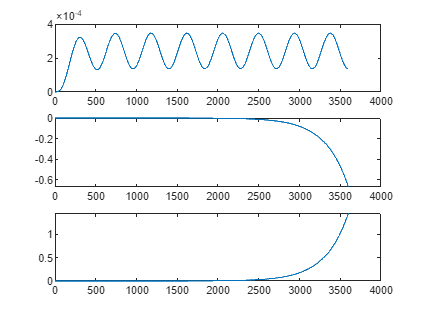

clear all
clc
close all

% Sim vars
SIMTIME = 3600;
SIMSTEP = 0.1;
simsize = SIMTIME/SIMSTEP+1;
n_contr = 9;
n_obsv = 9;
time = 0:SIMSTEP:SIMTIME;

z33 = zeros(3,3);
% x = [Np, Ep, psip, u, v, r, tauN, tauE, tauPSI]
% Ship characteristics
[M, D, Athr] = loadvars();
A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
Bvw = Bv;
wave_ampl = [2, 2, 0];
wave_length = [70 70 70];
C = [eye(9,9)];
eig(A);
rank(ctrb(A, B));
rank(obsv(A, C));

x0 = zeros(n_contr, 1);
bias = [0, 0, 0];
ref = zeros(3,1);
sim("plant.slx")

Np = y.Data(:,1); Ep = y.Data(:,2); PSIp = y.Data(:,3);

figure
subplot(311), plot(time, Np)
subplot(312), plot(time, Ep)
subplot(313), plot(time, PSIp)

## FSF with integral action

z33 = zeros(3,3);
% x = [Np, Ep, psip, u, v, r, tauN, tauE, tauPSI]
% Ship characteristics
[M, D, Athr] = loadvars();
A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
C = [eye(3,9)];
eig(A)

ans =          0
         0
    0.0011
    0.0035
         0
   -0.0069
   -0.0067
   -0.0050
   -0.0056


rank(ctrb(A, B))

ans = 9


n_augm = 3;
Ai = [A zeros(9,3);
      -C zeros(3,3)];
Bi = [B; zeros(3,3)];
N = [zeros(9,3); eye(3)];
Bvi = [Bv; zeros(3, 3)];
Ci = [C zeros(3,3)];
rank(ctrb(Ai, Bi))

ans = 12


lambda_pos = [-1. -1.2 -1.4]

lambda_pos =    -1.0000   -1.2000   -1.4000


lambda_vel = [-0.8 -0.9 -0.7]

lambda_vel =    -0.8000   -0.9000   -0.7000


lambda_tau = [-0.05+0.05i -0.05-0.05i -0.09]

lambda_tau =   -0.0500 + 0.0500i  -0.0500 - 0.0500i  -0.0900 + 0.0000i


lambda_int = [-5 -6 -7]

lambda_int =     -5    -6    -7


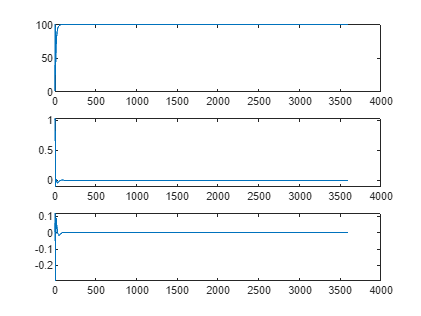

des_lambda = [lambda_pos lambda_vel lambda_tau lambda_int];
K = place(Ai, Bi, des_lambda);
Kfs = K(:,1:n_contr);
Ki = -K(:,end-n_augm+1:end);

ref = [100 0 0];
bias = [5, 1, 0];
x0 = zeros(n_contr, 1);
x0(1:3) = [1, 1, 0];
x0int = x0(1:3);
sim("fsf_int.slx")

Np = y.Data(:,1); Ep = y.Data(:,2); PSIp = y.Data(:,3);
tauN = states.Data(:,7); tauE = states.Data(:,8); tauPSI = states.Data(:,9); 

figure
subplot(311), plot(time, Np)
subplot(312), plot(time, Ep)
subplot(313), plot(time, PSIp)

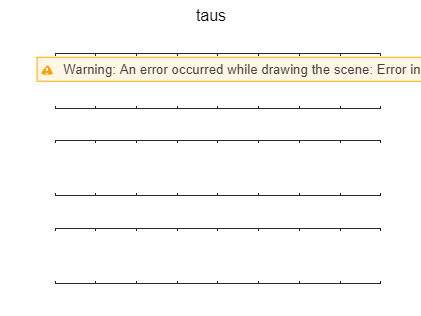

figure, sgtitle("taus")
subplot(311), plot(time, tauN)
subplot(312), plot(time, tauE)
subplot(313), plot(time, tauPSI)

## LQR with integral action

A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];
B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
Bvw = Bv;
wave_ampl = [2, 2, 0].*0;
wave_length = [70 70 70];
C = eye(3,9);
n_augm = 3;

Ai = [A zeros(9,3);
      -C zeros(3,3)];
Bi = [B; zeros(3,3)];
N = [zeros(9,3); eye(3)];
Bvi = [Bv; zeros(3, 3)];
Ci = [C zeros(3,3)];
rank(ctrb(Ai, Bi))

ans = 12

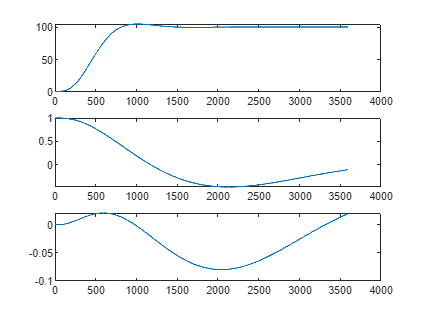


Q = diag([1e5, 1e5, 1e5, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 10, 10, 10]);
R = diag([0.01, 0.01, 0.01]);
K = lqr(Ai, Bi, Q, R);
Klqr = K(:,1:n_contr);
Ki = -K(:,end-n_augm+1:end);

ref = [100 0 0];
bias = [5, 1, 0];
x0 = zeros(n_contr, 1);
x0(1:3) = [1, 1, 0];
x0int = zeros(n_augm ,1);
sim("lqr_int.slx")

Np = y.Data(:,1); Ep = y.Data(:,2); PSIp = y.Data(:,3);
tauN = states.Data(:,7); tauE = states.Data(:,8); tauPSI = states.Data(:,9); 

figure
subplot(311), plot(time, Np)
subplot(312), plot(time, Ep)
subplot(313), plot(time, PSIp)

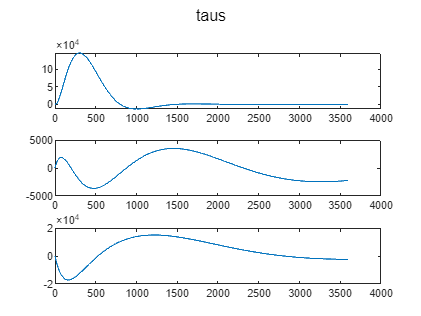

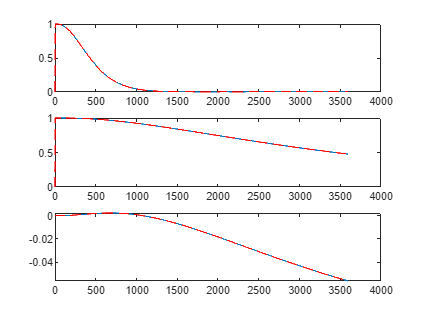

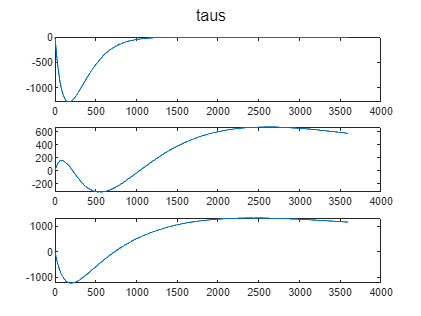

figure, sgtitle("taus")
subplot(311), plot(time, tauN)
subplot(312), plot(time, tauE)
subplot(313), plot(time, tauPSI)

## LQR with LuenObse and Integral action

A = [z33,    eye(3),    z33;
     z33, -inv(M)*D, inv(M);
     z33,       z33,   Athr];

A =          0         0         0    1.0000         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
         0         0         0   -0.0069         0         0    0.0000         0         0
         0         0         0         0    0.0011   -0.0011         0    0.0000    0.0000
         0         0         0         0   -0.0001    0.0035         0    0.0000   -0.0000
         0         0         0         0         0         0   -0.0067         0         0
         0         0         0         0         0         0         0   -0.0050         0
         0         0         0         0         0         0         0         0   -0.0056


B = [z33, z33, -Athr]';
Bv = [z33, inv(M), z33]';
Bvw = Bv;
wave_ampl = [2, 2, 0];
wave_length = [70 70 70];
C = [eye(9,9)];
n_augm = 3;

Ai = [A zeros(9,3);
      -C(1:3,:) zeros(3,3)];
Bi = [B; zeros(3,3)];
N = [zeros(9,3); eye(3)];
Bvi = [Bv; zeros(3, 3)];
Ci = [C(1:3,:) zeros(3,3)];
rank(ctrb(Ai, Bi))

ans = 12

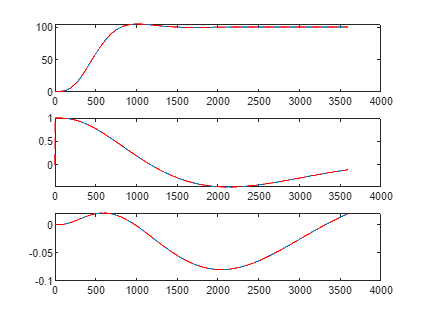


Q = diag([1e5, 1e5, 1e5, 0.01, 0.01, 0.01, 0.01, 0.01, 0.01, 10, 10, 10]);
R = diag([0.01, 0.01, 0.01]);
K = lqr(Ai, Bi, Q, R);
Klqr = K(:,1:n_contr);
Ki = -K(:,end-n_augm+1:end);

Ak = Ai-Bi*K;
eig_cl = eig(Ak);

factor = 1.5;
des_obsv_poles = (min(real(eig_cl))*factor)-(1:n_obsv);
L = place(A', C', des_obsv_poles)';

ref = [100 0 0];
bias = [5, 1, 0];
x0 = zeros(n_contr, 1);
x0(1:3) = [1, 1, 0];
x0_est = zeros(n_obsv, 1);
x0int = x0(1:3);
sim("lqr_obs_int.slx")

Np = y.Data(:,1); Ep = y.Data(:,2); PSIp = y.Data(:,3);
Np_est = y_est.Data(:,1); Ep_est = y_est.Data(:,2); PSIp_est = y_est.Data(:,3);
tauN = states.Data(:,7); tauE = states.Data(:,8); tauPSI = states.Data(:,9); 

figure
subplot(311), plot(time, Np), hold on, plot(time, Np_est, "r--")
subplot(312), plot(time, Ep), hold on, plot(time, Ep_est, "r--")
subplot(313), plot(time, PSIp), hold on, plot(time, PSIp_est, "r--")

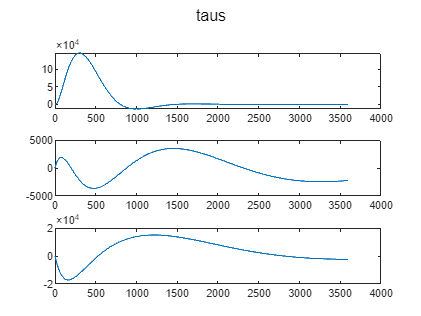

Q =      1     0     0
     0     1     0
     0     0     1


R =     0.0100         0         0
         0    0.0100         0
         0         0    0.0100


sensors =      1     2     3


Error using ss/kalman
Cannot compute a convergent Kalman filter (the Riccati solution P and gain matrix L are infinite). 
This could be because: 
  * A has unstable modes that are not observable through C, 
  * The QN,RN,NN values are too large, 
  * [QN NN;NN' RN] is indefinite, 
  * The E matrix in the state equation is singular.

figure, sgtitle("taus")
subplot(311), plot(time, tauN)
subplot(312), plot(time, tauE)
subplot(313), plot(time, tauPSI)